# Loading Data, probe registraton

*Please contact Ted (huppert1@pitt.edu) or Hendrik (hes73@pitt.edu) to request more demos, suggestions, feedback, etc. We will update this script as needed. *

## 1.1 Loading Data

This toolbox can load almost all existing NIRS files. If you have a new NIRS system or a file that cannot be loaded by the toolbox, please reach out to us.

Downloading 'demo_data' from the server

clear all
clc

if(ismac | isunix)
    root_dir = ['/Users/' getenv('USER') '/Desktop/tmp'];
else
    root_dir = [getenv('UserProfile') '\Desktop\tmp'];
 end

if(~exist(root_dir,'dir') || ~exist(fullfile(root_dir,'demo_data'),'dir'))
    mkdir(root_dir);
    disp('downloading sample data from bitbucket.org site');
    %% download the dataset
    urlwrite('http://huppertlab.net/wp-content/uploads/2024/05/demo_data.zip', ...
        [root_dir filesep 'demo_data.zip'])
    % This command will download the demo_data.zip file from the server.  This
    % step can be skipped if you already downloaded this. This could take a few minutes if your internet conenction is slow
    % The file is about 90Mb in size.
    
    % unzip the data
    unzip([root_dir filesep 'demo_data.zip'],[root_dir filesep]);
    % This will unpack a folder called "data" containing two groups (G1 & G2).
    % A script "simulation.m" is included which was used to generate the data
    % (but is not intended to be run).  The data was simulated from a set of
    % experimental resting state NIRS data with simulated evoked responses
    % added to it to demostrate this analysis pipeline.
    
else
    disp(['Data found in: ' root_dir ': skipping download']);
end

Data found in: /Users/hendriksantosa/Desktop/tmp: skipping download


This example will download one dataset (68 NIRS files) from the toolbox to your local computer ('Desktop/tmp')

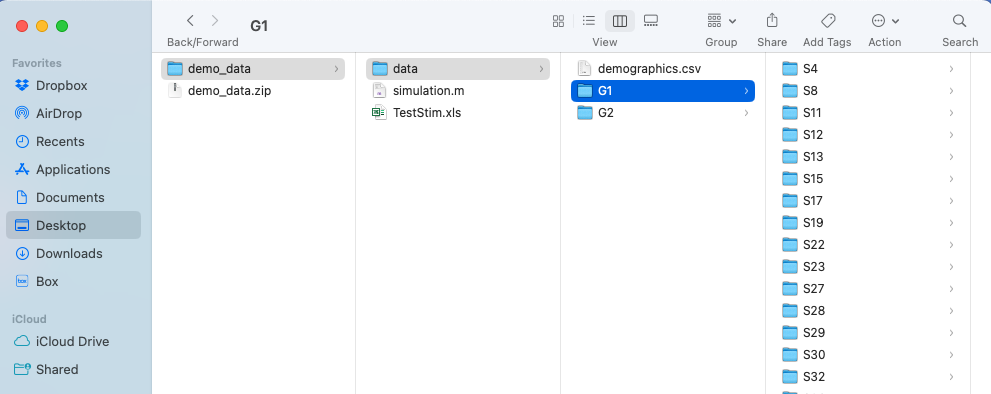

Inside this 'demo_data', there are two subfolders 'G1' and 'G2', each containing several subjects. These subfolders contain individual  single *.nirs file. 

There are two option to load the NIRS data:

**Option 1**: Loading a single NIRS data

Please set your current folder to one NIRS file, for example: '/Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S68'

raw1 = nirs.io.loadDotNirs('scan.nirs')

Loading scan.nirs
Empty file found (skipping):
scan.nirs

raw1 = 

  0×0 Data array with properties:

    description
    data
    probe
    time
    Fm
    auxillary
    stimulus
    demographics
    Fs




% Here is another option for different NIRS datasets
% nirs.io.loadNIRx
% nirs.io.loadBiopacNIR
% etc

**Option 2**: Loading all files in a specific directory **(Recommended)**

This function loads a whole directory of *.nirs files. The second argument tells the function to use the first level of folder names to specify group id ('group') and the seond level to specify subject id ('subject'). The 'nirs.io.loadDirectory' module will automatically read any type of NIRS file (do not specify *.nirs or *wl, etc)

raw = nirs.io.loadDirectory([root_dir filesep 'demo_data' filesep 'data'], {'group', 'subject'});

Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S11/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S12/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S13/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S15/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S17/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S19/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S22/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S23/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S27/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S28/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S29/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S30/scan.nirs
Loading /Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S32/scan.nirs
Loading /Users/hendriksantosa/Desktop/


% To see demographics (created from 'nirs.io.loadDirectory')
nirs.createDemographicsTable(raw)

ans = 68×2 table
    group     subject
    ______    _______

    {'G1'}    {'S11'}
    {'G1'}    {'S12'}
    {'G1'}    {'S13'}
    {'G1'}    {'S15'}
    {'G1'}    {'S17'}
    {'G1'}    {'S19'}
    {'G1'}    {'S22'}
    {'G1'}    {'S23'}
    {'G1'}    {'S27'}
    {'G1'}    {'S28'}
    {'G1'}    {'S29'}
    {'G1'}    {'S30'}
    {'G1'}    {'S32'}
    {'G1'}    {'S36'}
    {'G1'}    {'S37'}
    {'G1'}    {'S38'}



% This raw file contain all the information which will be used in the next
% data processing: data, probe, time, Fs, stimulus, demographics, etc
raw(1)

ans =   Data with properties:

     description: '/Users/hendriksantosa/Desktop/tmp/demo_data/data/G1/S11/scan.nirs'
            data: [3505×70 double]
           probe: [1×1 nirs.core.Probe]
            time: [3505×1 double]
              Fm: 0
       auxillary: [1×1 Dictionary]
        stimulus: [1×1 Dictionary]
    demographics: [1×1 Dictionary]
              Fs: 10


To see the raw data

figure; raw(1).draw


To see the probe information

raw(1).probe.link

ans = 70×3 table
    source    detector    type
    ______    ________    ____

      1          1        690 
      1          1        830 
      1          2        690 
      1          2        830 
      1          6        690 
      1          6        830 
      2          1        690 
      2          1        830 
      2          2        690 
      2          2        830 
      2          3        690 
      2          3        830 
      2          6        690 
      2          6        830 
      3          1        690 
      3          1        830 


To plot the raw(1) data and stimulus info

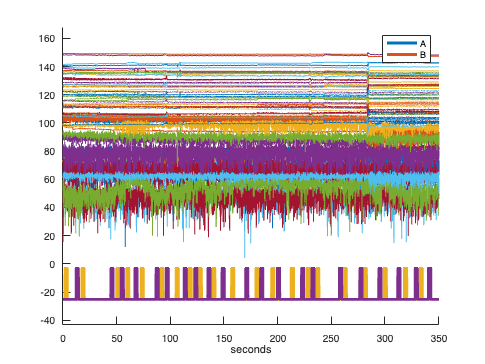

raw(1).draw

To plot hbo and hbr first channel of 690nm data (S1-D1) and 830nm data (S1-D1)

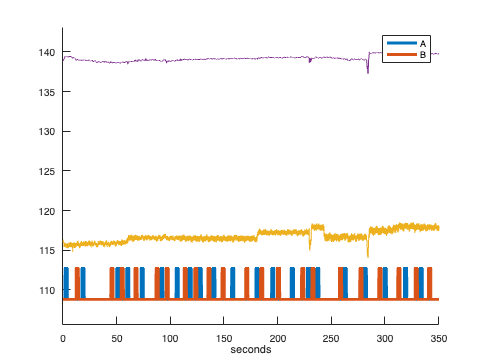

figure; raw(1).draw([1 2])

To plot probe configuration

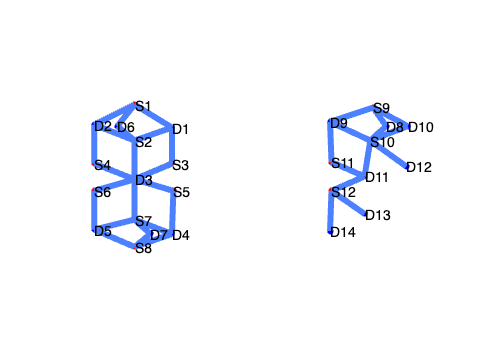

figure; raw(1).probe.draw

GUI for visualization

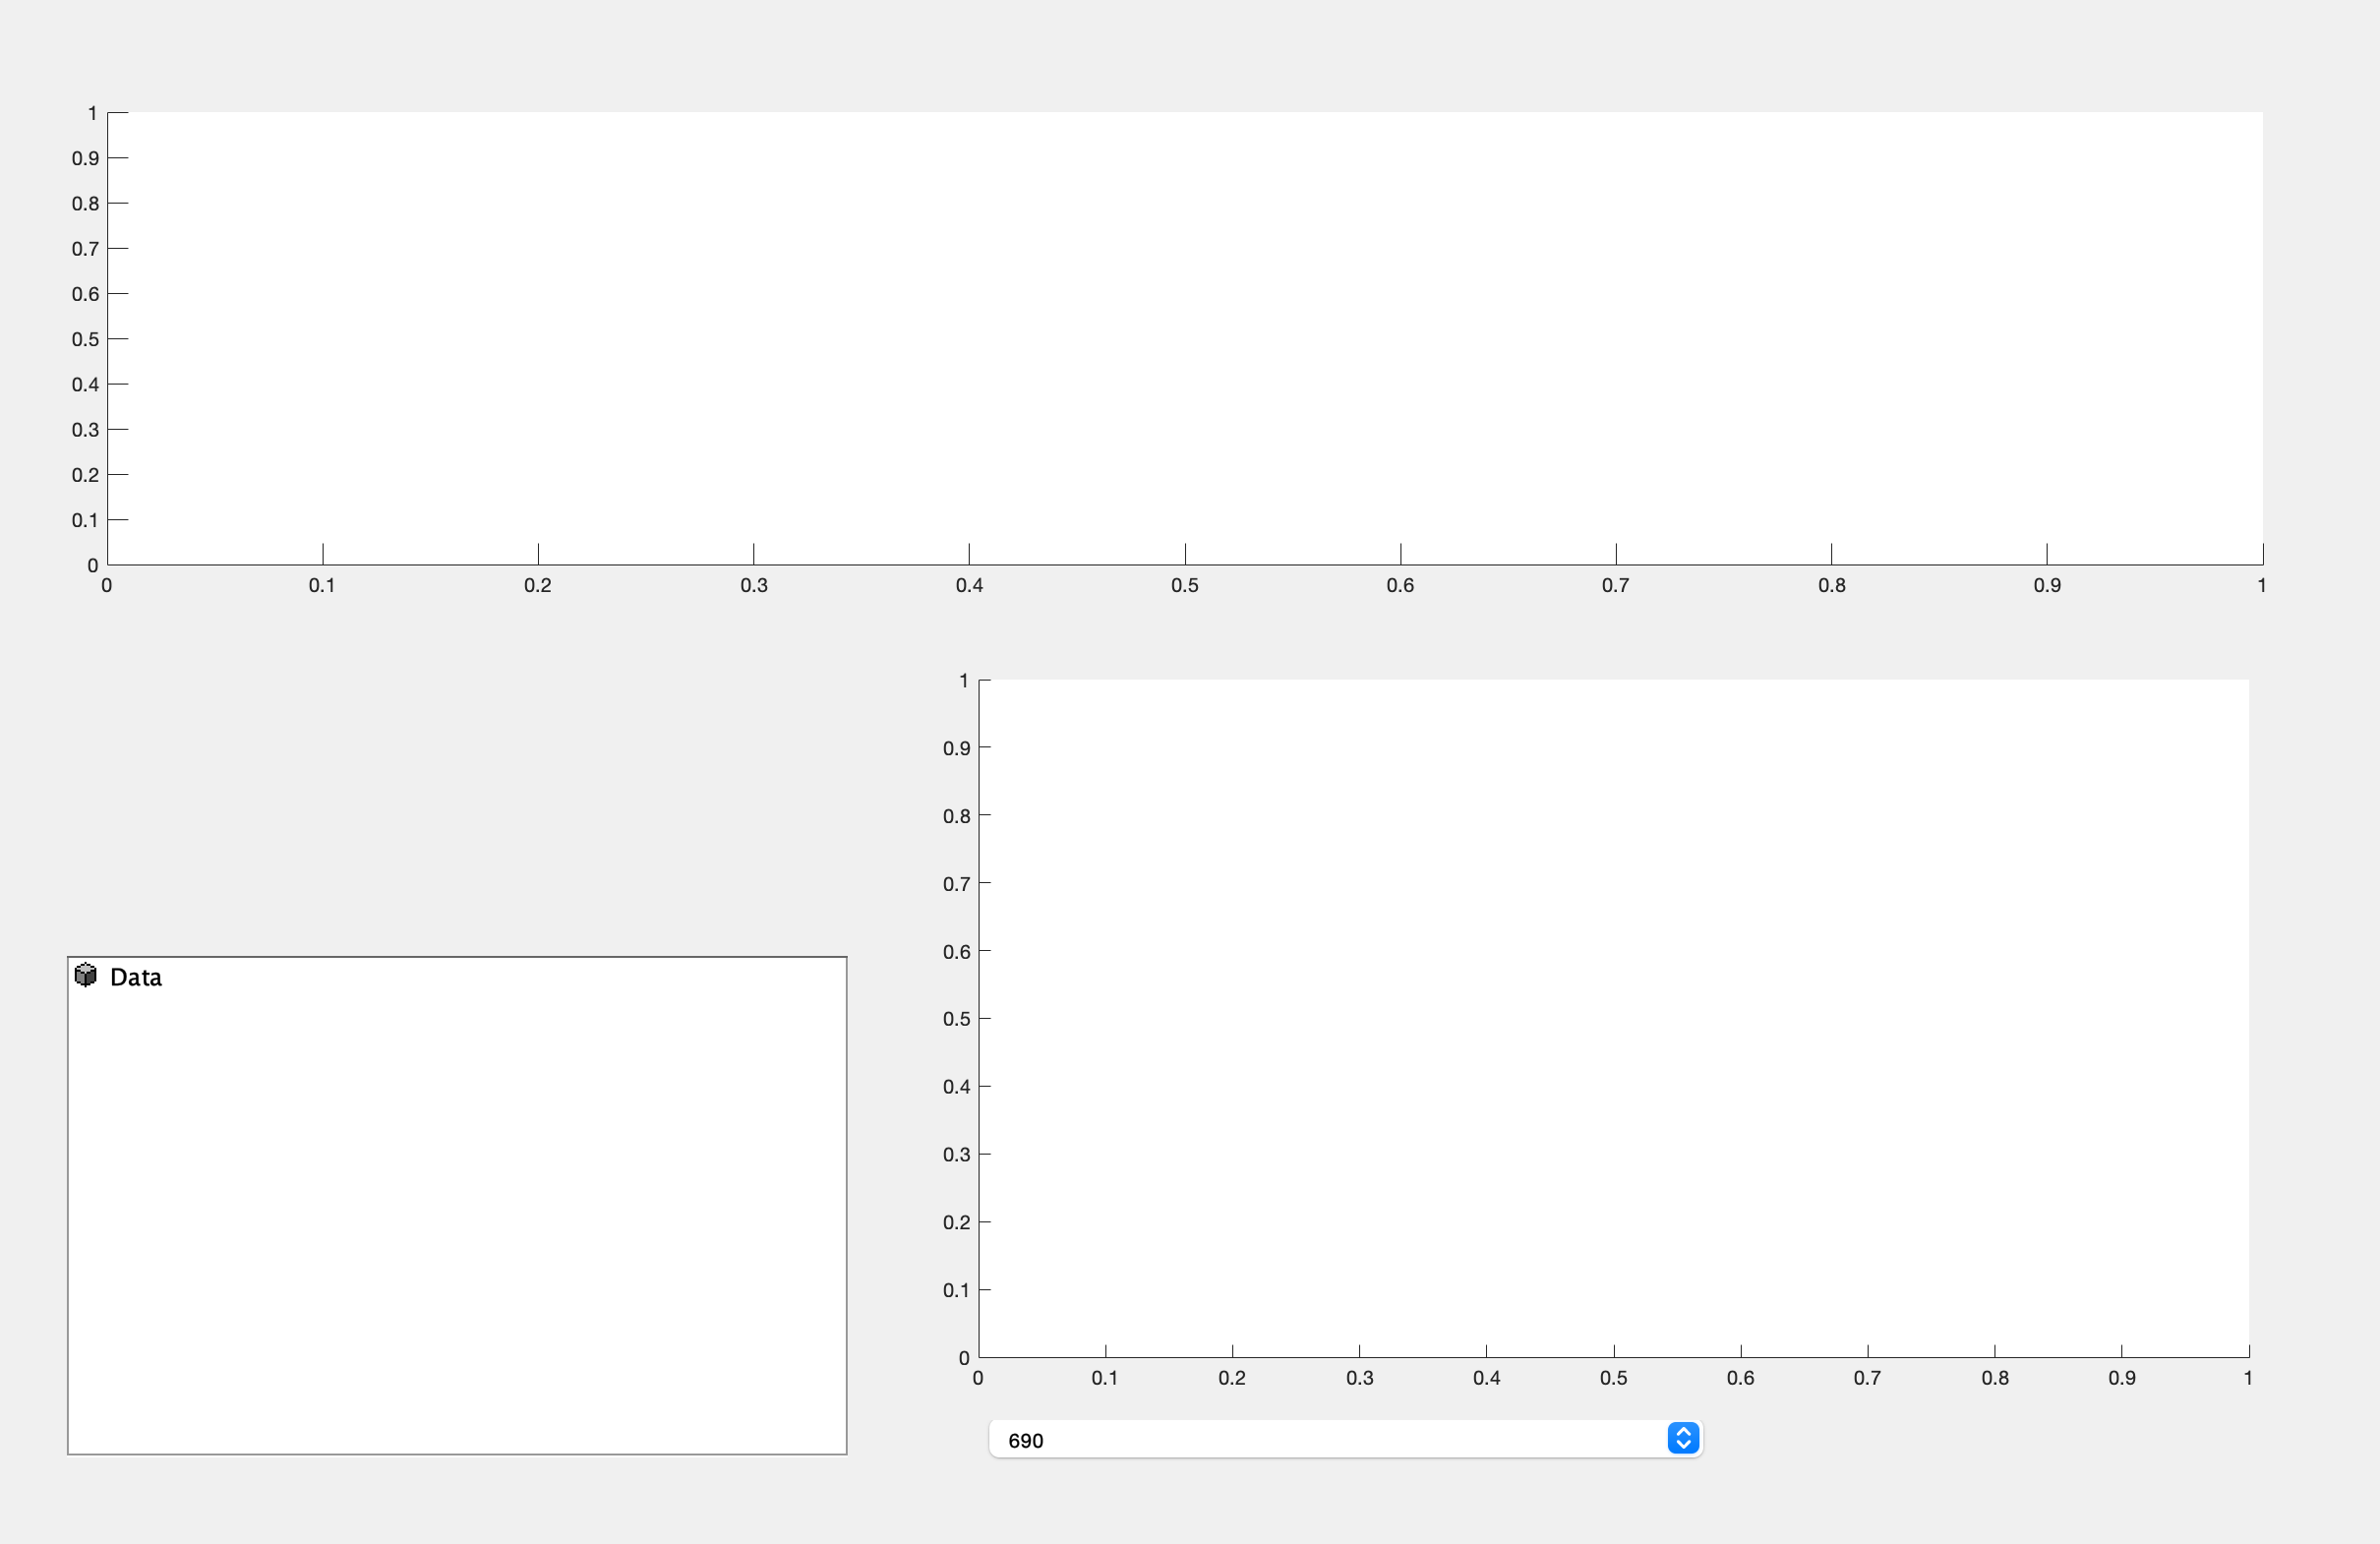

ans =   TimeSeriesViewer with no properties.


nirs.viz.TimeSeriesViewer(raw)

## 1.2 Remove Data

This example shows how to remove files from the dataset. For example, we want to remove subjects S11, S12, S61, and S64

lst = find(ismember(nirs.createDemographicsTable(raw).subject, {'S11', 'S12', 'S61', 'S64'}))

lst =      1
     2
    64
    65



raw2 = raw

raw2 =   16×1 Data array with properties:

    description
    data
    probe
    time
    Fm
    auxillary
    stimulus
    demographics
    Fs


raw2(lst) = [] %This raw2 will contain all previous file except S11, S12, S61, and S64

raw2 =   16×1 Data array with properties:

    description
    data
    probe
    time
    Fm
    auxillary
    stimulus
    demographics
    Fs


## 1.3 Quality Report

### 1.3.1 Scalp Coupling Index

This module computes "scalp coupling index (SCI)" over all channels. This SCI is based on the cross correlation of the two wavelengths of optical data for each channel around the cardiac frequency. In the best data, the cardiac signals at two wavelengths are correlated, thus yielding an SCI close to 1. In contrast, noisy cardiac signals led to a lower SCI value (close to 0). For details, see this paper: Pollonini et. al., 2016 ([https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5175555/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5175555/))

% This module will show the sci from every channel in raw(1)
tblSCI = nirs.util.scalp_coupling_index(raw(1))

tblSCI = 35×5 table
    source    detector       sci          power       fpower 
    ______    ________    __________    __________    _______

      1          1           0.14961    3.6029e-05     1.3568
      1          2          0.021173    6.5375e-05      1.003
      1          6           0.45878    2.7243e-05    0.79612
      2          1        -0.0074845    0.00015782    0.81181
      2          2          0.045611    3.1077e-05      1.003
      2          3          0.030998    5.7177e-05     1.1171
      2          6           0.30567    2.5742e-05    0.78899
      3          1          0.059721     0.0013697      1.558
      3          3         -0.011814    2.5525e-05     1.2298
      4          2           0.34889    0.00027238     1.0044
      4          3          -0.01574      2.28e-05     1.4296
   

## 1.4 Export results

We can export all the tables to an Excel file: 

writetable(tblSCI, 'tblSCI.xlsx') %This will create the excel file of tblSCI in your current folder

## 1.5 Probe registration

This example show how to register 2D probe into Colin27

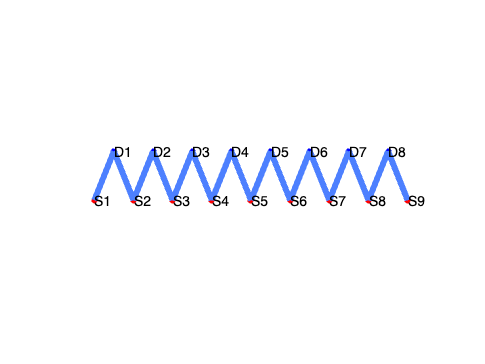

clear all
clc

raw = nirs.testing.simData;
figure; raw.probe.draw

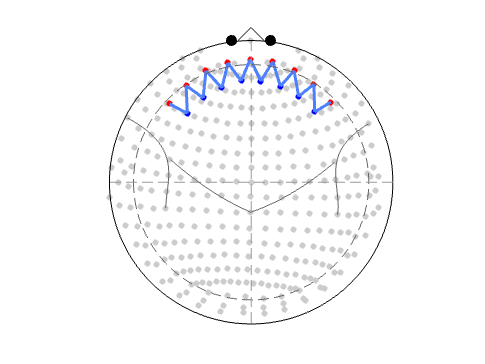


% let's just center this on the forehead
Name{1}='FpZ';
xyz(1,:)=[0 0 0];
Type{1}='FID-anchor';  % This is an anchor point
Units{1}='mm';

Name{2}='Cz';
xyz(2,:)=[0 100 0];
Type{2}='FID-attractor';  % This is an attractor
Units{2}='mm';

Name{3}='T7';
xyz(3,:)=[-200 0 0];
Type{3}='FID-attractor';  % This is an attractor
Units{3}='mm';

Name{4}='T8';
xyz(4,:)=[200 0 0];
Type{4}='FID-attractor';  % This is an attractor
Units{4}='mm';

% Create table from that position information
fid=table(Name',xyz(:,1),xyz(:,2),xyz(:,3),Type',Units',...
    'VariableNames',{'Name','X','Y','Z','Type','Units'});
% and concatinate it to the probe
raw.probe.optodes=[raw.probe.optodes; fid];

% We can change the headsize
headsize=Dictionary();
headsize('circumference')=430;  %mm

% Register probe to the head
raw.probe=nirs.util.registerprobe1020(raw.probe,headsize);

% To visualize
figure; raw.probe.draw1020


% Load Colin27 atlas mesh
mesh=nirs.registration.Colin27.mesh;

mesh(1).fiducials.Draw(:)=false;   
% the mesh is also nested (4-layers), so let's turn off the display of the
% skin, skull, and dura
mesh(1).transparency=0;
mesh(2).transparency=0;
mesh(3).transparency=0;

% Register it to the probe 
raw.probe=raw.probe.register_mesh2probe(mesh);

% This is all the option: 
raw.probe.defaultdrawfcn = '?'

Here are the options for drawing configurations
    {'10-20'                    }    {'10-20 mercator projection map'                                   }
    {'10-20 zoom'               }    {'10-20 mercator with restricted view'                             }
    {'10-20 map'                }    {'10-20 mercator with underlain image'                             }
    {'10-20 map zoom'           }    {'10-20 mercator with underlain image'                             }
    {'10-20 label'              }    {'10-20 mercator projection map'                                   }
    {'10-20 map zoom label'     }    {'10-20 mercator with underlain image'                             }
    {'10-20 ball'               }    {'10-20 with underlying circles for heat maps'                     }
    {'10-20 ball zoom'          }    {'10-20 with underlying circles for heat maps with restricted view'}
    {'3D'                       }    {'3D line drawing '                                                

raw =   Data with properties:

     description: []
            data: [3001×32 double]
           probe: [1×1 nirs.core.Probe1020]
            time: [3001×1 double]
              Fm: 0
       auxillary: [1×1 Dictionary]
        stimulus: [1×1 Dictionary]
    demographics: [1×1 Dictionary]
              Fs: 10


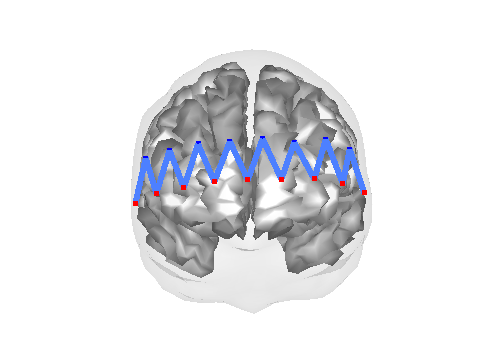


% change the default draw behavior and show the results
raw.probe.defaultdrawfcn='3D mesh (frontal)';
figure; raw.probe.draw;

## 1.6 Probe sensitivity

We can show how your probe cofiguration relative to Broadman area, see this paper: [https://pubmed.ncbi.nlm.nih.gov/28948192](https://pubmed.ncbi.nlm.nih.gov/28948192), Fig. 9

lstName = {'ba-9_l', 'ba-9_r', 'ba-10_l', 'ba-10_r'}

lstName = 1×4 cell array
    {'ba-9_l'}    {'ba-9_r'}    {'ba-10_l'}    {'ba-10_r'}


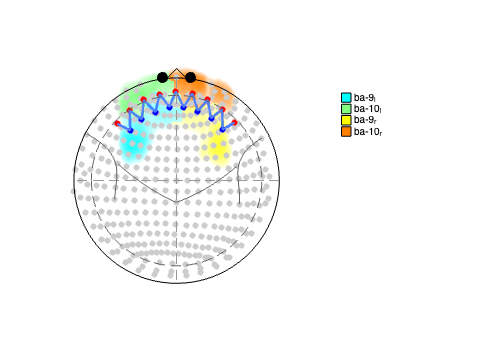

nirs.util.regionmap(lstName, raw(1).probe) 